# Expander, Compressor

### Expander and compressor are two types of audio processing tools used to control the dynamic range of audio signals. The dynamic range is the difference between the loudest and softest parts of a sound or music piece.

### First we define a single which has a main frequency index but it's amplitude varies in 3 parts of the signal.

clc;
clear

w0 = pi * 0.15;
n = [0:199; 200:399; 400:599];
A = [2 4 0.5];
x = cos(w0 * n) .* A';
x = x';
x = x(1:end);
n = n';
n=n(1:end);

# 3-3-a

### We want to prove that the absolute mean of each part of the signal is 2pi/A, and suqare mean for each part of the signal is going to be 1/2 A^2

x_divided=[199 399 599];% indexes show the row of the last index of each part
abs_mean=[];
count1=0;
for i=1:x_divided(1)
    count1=count1+abs(x(i));
end
abs_mean(1)=count1/x_divided(1);

count1=0;
for i=x_divided(1)+1:x_divided(2)
    count1=count1+abs(x(i));
end
abs_mean(2)=count1/(x_divided(2)-x_divided(1));

count1=0;
for i=x_divided(2)+1:x_divided(3)
    count1=count1+abs(x(i));
end
abs_mean(3)=count1/(x_divided(3)-x_divided(2));
abs_mean_theoric=(2/pi).*A;
abs_mean

abs_mean =     1.2681    2.5323    0.3332


abs_mean_theoric

abs_mean_theoric =     1.2732    2.5465    0.3183





square_mean=[];
count1=0;
for i=1:x_divided(1);
    count1=count1+(x(i))^2;
end
square_mean(1)=count1/x_divided(1);

count1=0;
for i=x_divided(1)+1:x_divided(2)
    count1=count1+(x(i))^2;
end
square_mean(2)=count1/(x_divided(2)-x_divided(1));

count1=0;
for i=x_divided(2)+1:x_divided(3)
    count1=count1+(x(i))^2;
end
square_mean(3)=count1/(x_divided(3)-x_divided(2));
square_mean_theoric=(0.5).*(A.^2);
square_mean

square_mean =     1.9941    7.9524    0.1875


square_mean_theoric

square_mean_theoric =     2.0000    8.0000    0.1250


# 3-3-b

### Next we define the control signal.

lambda = 0.9;
c0 = 1.5;
rho = 10;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

### Defining gain processor unit

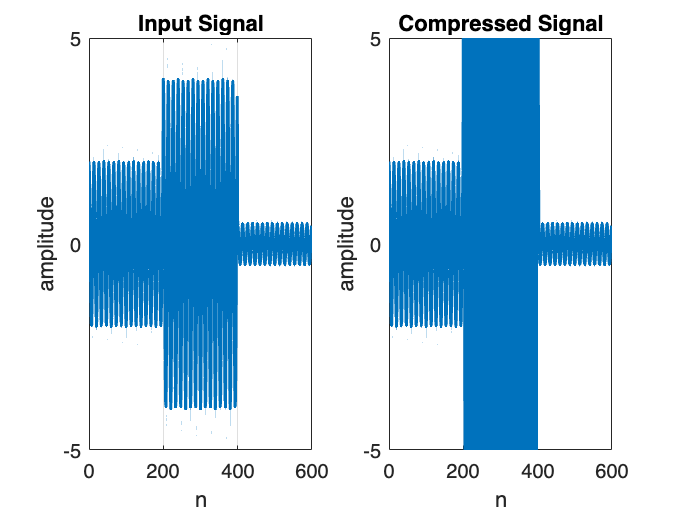

gn = ones(1, length(cn));
gn(cn >= c0) = (cn(cn >= c0) / c0) .^ (rho - 1);
yn = gn .* x;

%% Illustrations
figure("Name", 'Input Signal vs Compressed Signal');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn, 'LineWidth', 1.5);
title('Compressed Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

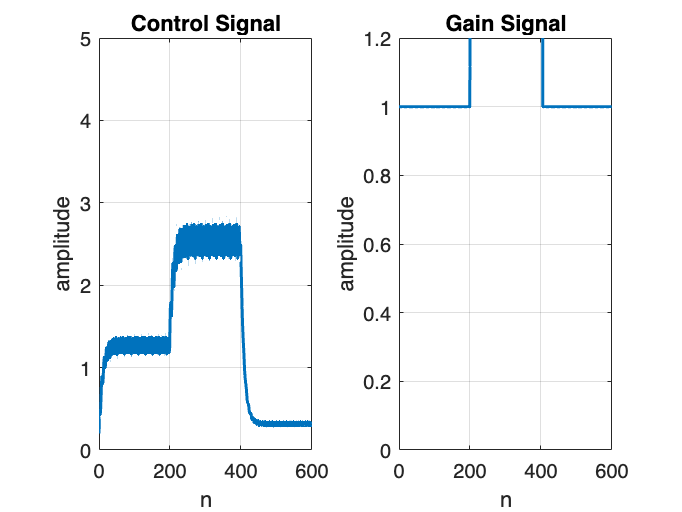


figure('Name', 'Contol Signal vs Gain Signal');
subplot(1, 2, 1);
plot(n, cn, 'LineWidth', 1.5);
title('Control Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 5]);
grid on;
subplot(1, 2, 2);
plot(n, gn, 'LineWidth', 1.5);
title('Gain Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

### Next we define smooted form of control signaland gain signal using moving average.

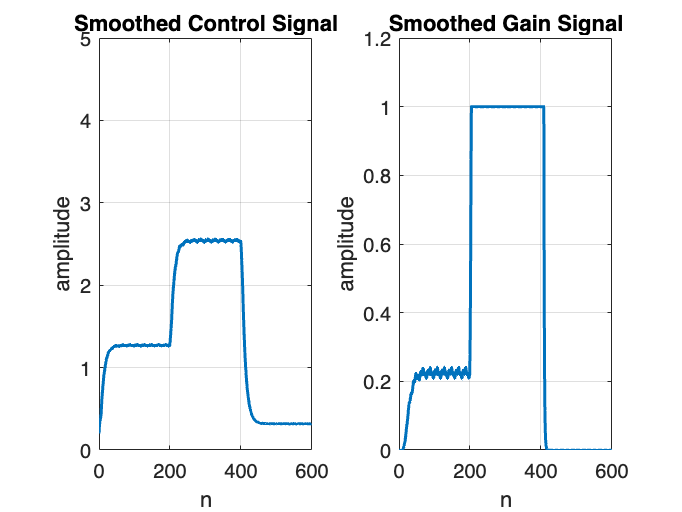

L = 7;
cn_smoothed = movmean(cn, [L - 1 0]);
gn_smoothed = ones(1, length(cn_smoothed));
gn_smoothed(cn_smoothed <= c0) = (cn_smoothed(cn_smoothed <= c0) / c0) .^ (rho - 1);
yn_smoothed = gn_smoothed .* x;

figure('Name', 'Smoothed Contol Signal vs Smoothed Gain Signal');
subplot(1, 2, 1);
plot(n, cn_smoothed, 'LineWidth', 1.5);
title('Smoothed Control Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 5]);
grid on;
subplot(1, 2, 2);
plot(n, gn_smoothed, 'LineWidth', 1.5);
title('Smoothed Gain Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

# 3-3-c

#### Now we check compressor with this parameters

rho=1/4 , lambda=0.9 , c0=1.5 

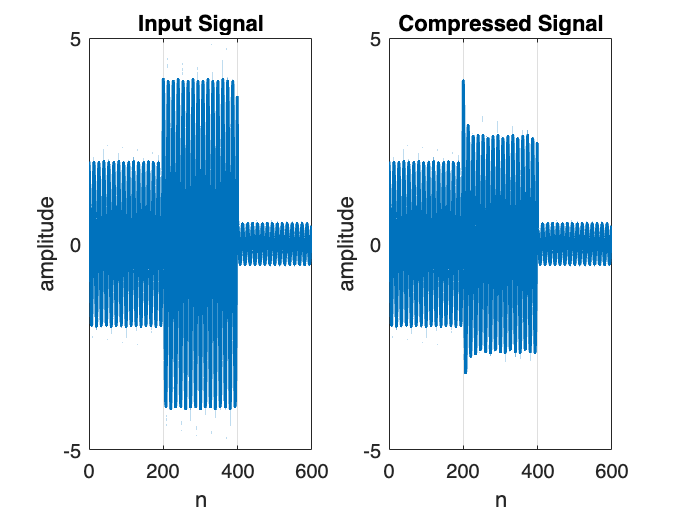

lambda = 0.9;
c0 = 1.5;
rho = 1/4;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

gn = ones(1, length(cn));
gn(cn >= c0) = (cn(cn >= c0) / c0) .^ (rho - 1);
yn = gn .* x;

%% Illustrations
figure("Name", 'Input Signal vs Compressed Signal');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn, 'LineWidth', 1.5);
title('Compressed Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

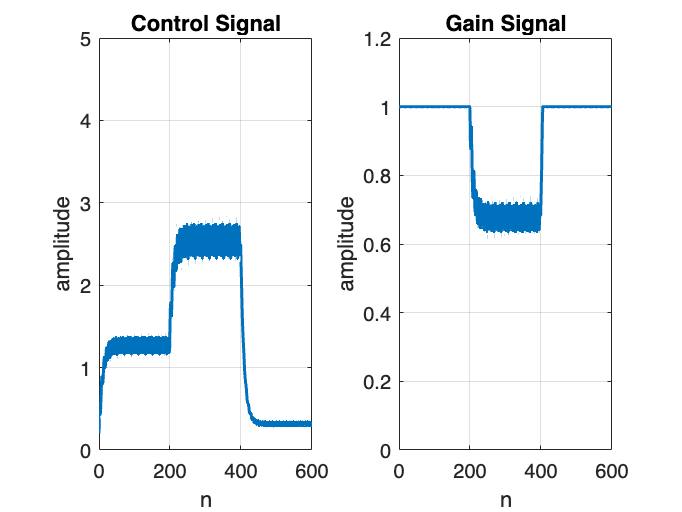


figure('Name', 'Contol Signal vs Gain Signal');
subplot(1, 2, 1);
plot(n, cn, 'LineWidth', 1.5);
title('Control Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 5]);
grid on;
subplot(1, 2, 2);
plot(n, gn, 'LineWidth', 1.5);
title('Gain Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

# 3-3-d

#### Now we check compressor with this parameters

rho=1/4 , lambda=0.9 , c0=1.5 

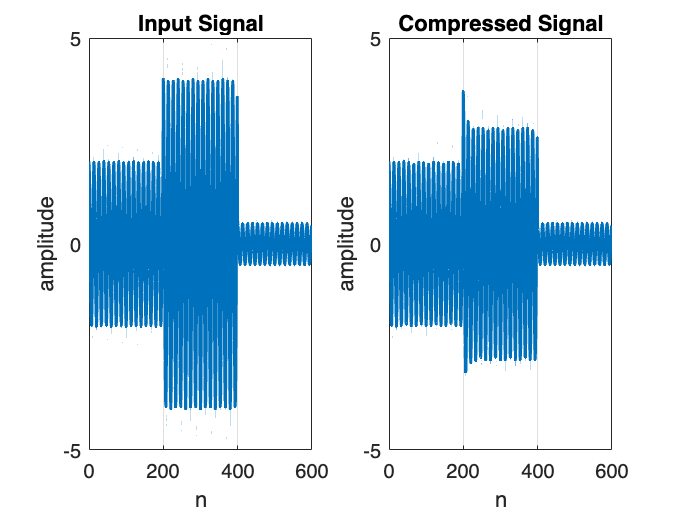

lambda = 0.9;
c0 = 1.3;
rho = 1/2;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

gn = ones(1, length(cn));
gn(cn >= c0) = (cn(cn >= c0) / c0) .^ (rho - 1);
yn = gn .* x;

%% Illustrations
figure("Name", 'Input Signal vs Compressed Signal');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn, 'LineWidth', 1.5);
title('Compressed Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

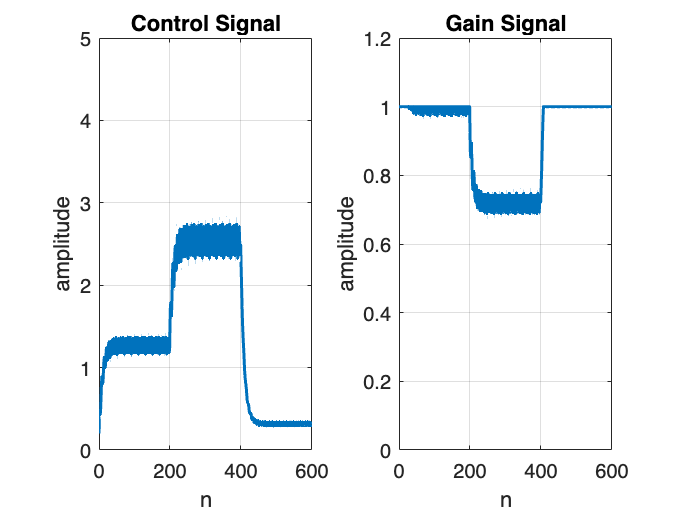


figure('Name', 'Contol Signal vs Gain Signal');
subplot(1, 2, 1);
plot(n, cn, 'LineWidth', 1.5);
title('Control Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 5]);
grid on;
subplot(1, 2, 2);
plot(n, gn, 'LineWidth', 1.5);
title('Gain Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;